# Übung: Segmentierung von Puzzleteilen

Feature Detection und Matching sind mächtige Werkzeuge, was aber, wenn wir eingrenzen möchten welche Objekte im Bild überhaupt untersucht werden sollen? Wenn wir beispielsweise einen störenden Hintergrund ignorieren, oder Fachwissen über die erwarteten Bilder nutzen möchten, benötigen wir einen Vorverarbeitungsschritt.

In dieser Übung werden wir gemeinsam einen solchen Vorverarbeitungsschritt implementieren, mit dem wir Puzzleteile in einem Bild finden, vom Hintergrund separieren und mit Labeln versehen können. In diesem Szenario gehen wir von verschiedensten möglichen (Bild-) Hintergründen aus. Was für Möglichkeiten haben wir eine solche Segmentierungsaufgabe anzugehen?

## Segmentierung

Die moderne Bildverarbeitung hat dafür (quasi Objekterkennung auf abweichenden Hintergründen) normalerweise eine klare Antwort: Deep Learning. Da uns allerdings die dafür nötige Datenmenge fehlt, werden wir eine Alternative bemühen müssen.

Wir werden unser Verfahren auf der Kantenerkennung aufbauen, somit benötigen wir keine festgelegten Farben (Green Screen) und sind weniger anfällig für Beleuchtungsunterschiede im Bild. Im speziellen verwenden wir den bekannten Canny-Algorithmus, dieser ist robust gegenüber Rauschen und liefert auch bei "schwächeren" Kanten gute Ergebnisse. Anschließend werden wir das erzeugte Kantenbild mit verschiedenen Verfahren in eine Maske umwandeln, die Puzzleteile im Bild klar vom Hintergrund trennt.

# Praxis

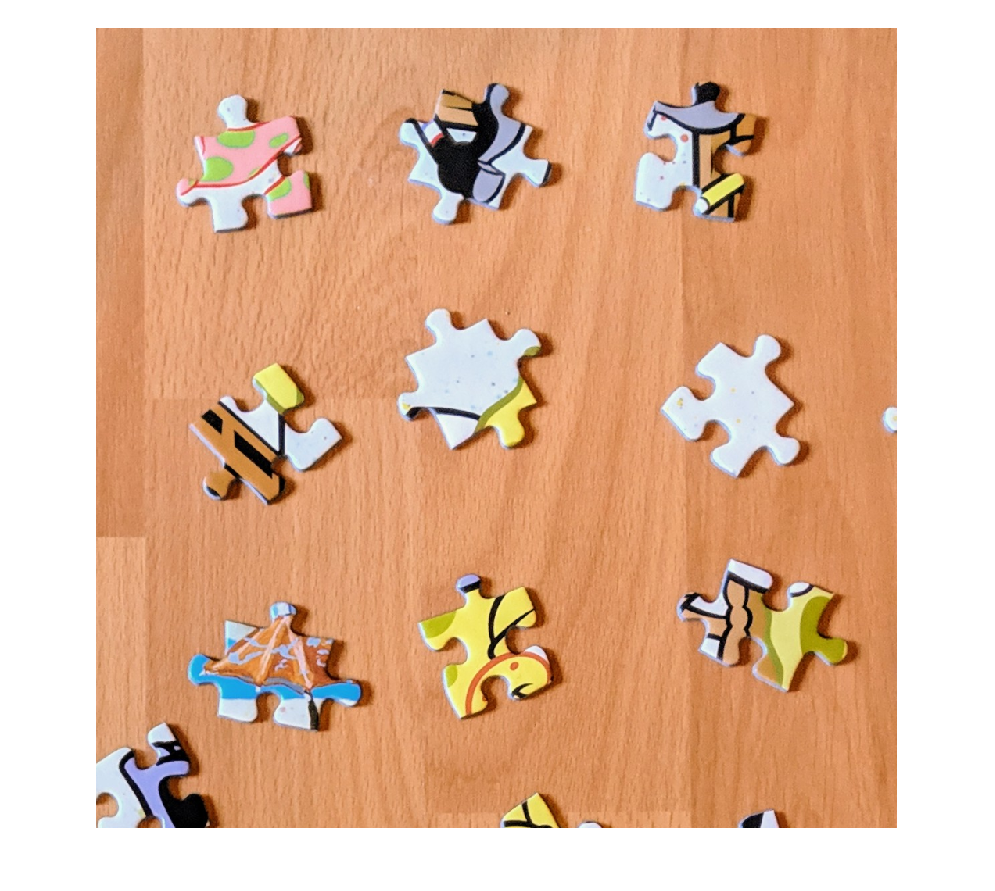

% Lädt die für die Übung benötigte Datei
piecesRGB = im2double(imread("images/puzzle/spongebob_pieces_bright.jpg"));
piecesRGB = imcrop(piecesRGB, [2000,0,1200,1200]);
imshow(piecesRGB)

## Schritt 1: Kantenbild erzeugen

Das Ausgangsbild ist in der Variable `piecesRGB` gespeichert. Die Funktion für Kantenbilder heißt `edge`, sie erwartet:

- ein *Grauwertbild.*

- die zu verwendende Methode, in unserem Fall `'Canny' für den Canny-Algorithmus.`

- `den Schwellwert*. Experimentiere mit diesem Parameter um alle Außenkanten der Puzzleteile zu erkennen und dabei möglichst wenig Kanten im Hintergrund zu haben.`

Lege eine Variable `mask` an, die das erzeugte Kantenbild enthält.

mask = edge(rgb2gray(piecesRGB), 'Canny', 0.14);

** Anmerkung*: der Canny-Algorithmus arbeitet intern mit 2 Schwellwerten, siehe [Dokumentation](https://www.mathworks.com/help/images/ref/edge.html).

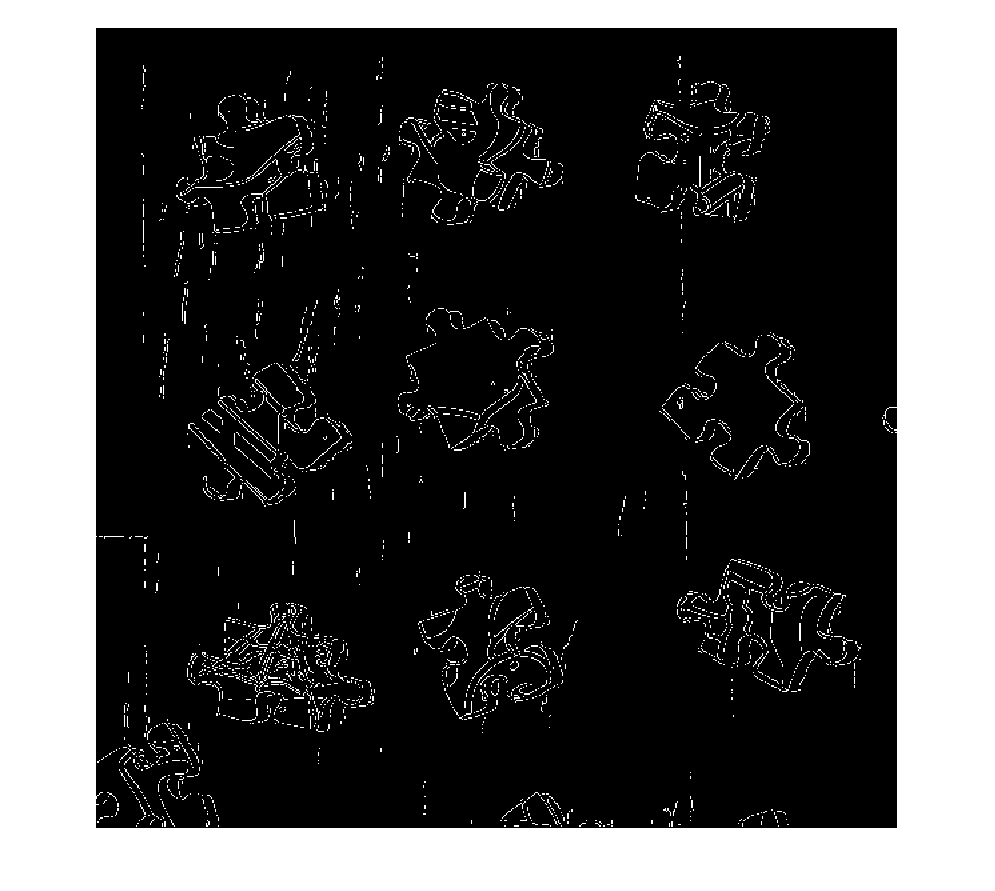

imshow(mask, [])

## Schritt 2: Lücken im Kantenbild schließen

Öffne das Kantenbild und vergrößere eines der Puzzleteile. Wie du siehst, sind die Kantenpixel gut erkannt worden, es finden sich dennoch viele Lücken. Wir werden Gauß Glättung verwenden um diese zu schließen. Dies ist ein naiver Ansatz, der aber für unsere Zwecke ausreichende Ergebnisse liefert. Der Vollständigkeit halber verlinke ich hier aber noch eine fortgeschrittenere [Alternative](https://www.peterkovesi.com/matlabfns/#edgelink).

Glätte das Kantenbild mit dem Gauß Filter (`imgaussfilt (das Eingabebild muss mit double konvertiert werden)`)  und einer dir sinnvoll erscheinenden Filtergröße - wie gesagt mit dem Ziel unterbrochene Kanten zu verbinden. Überschreibe die `mask` Variable mit dem Ergebnis.

mask = imgaussfilt(double(mask), 2);

Error using imgaussfilt
Expected A to be one of these types:

uint8, uint16, uint32, int8, int16, int32, single, double

Instead its type was logical.

Error in imgaussfilt>parseInputs (line 386)
validateattributes(A, supportedClasses, supportedImageAttributes, mfilename, 'A');

Error in imgaussfilt (

imshow(mask, [])

## Schritt 3: Umwandeln in eine Maske

% Um unterbrochene Kanten zu vermeiden, wird mit dem Sensitivity Parameter
% effektiv der Treshold für die Binärisierung ausgeschaltet.
mask = imbinarize(mask, "adaptive", "Sensitivity", 1.0);

imshow(mask, [])

% Anmerkung: der Flood Fill Algorithmus beginnt immer bei Koordinate (1 1),
% daher muss darauf geachtet werden, dass an dieser Position keine Kante
% erkannt wird.
mask = imcomplement(imfill(mask, [1 1]) - mask);

imshow(mask, [])

## Schritt 4: Entfernen von Ausreißern

% Wie stark Ränder von Flächen in der Maske erodiert werden sollen, um eine
% Aufweichung der Kanten durch die Gauß Klättung zu verhindern.
mask = imerode(mask, strel('disk', 5));

imshow(mask, [])

% Zusammenhängende Flächen in der Maske die weniger als minAreaSize Pixel
% groß sind werden entfernt, anpassen je nach Auflösung.
mask = bwareaopen(mask, 1000);

imshow(mask, [])

## Schritt 5: Anwendung der erzeugten Maske visualisieren

imshow(piecesRGB .* mask, [])

# Vergleich: Ausgangsbild & maskiertes gelabeltes Ergebnis

[labeled,labelCount] = bwlabel(mask);
index = 1;
labelOverlayed = piecesRGB .* mask;
while index <= labelCount
    labelOverlayed = insertText(labelOverlayed, ...
        regionprops(labeled==index,'Centroid').Centroid, ...
        index, ...
        "FontSize",36,"BoxOpacity",.75);
    index = index + 1;
end
montage({piecesRGB, labelOverlayed})

# Spoiler: Geeignete Werte für die gezeigten Verfahren